clear variables
close all
load('Tests/RPC_TT_test/e4_LNA_IR/rpc_e4_data.mat')

[~,n_fpoint] = size(gain_train);
m = 2;
xi_train = training_samples(1:200,:);
y_train = gain_train(1:200,:);
y_test = gain_test;
f_k = 1:100;



tic
[y_predict,n_rpc,d_rpc] = rpc_total(xi_train,y_train(:,f_k),test_samples,m,'Hermite',0.3,0.01,5e-3);
toc

Elapsed time is 1.922500 seconds.


norm(y_predict-y_test(:,f_k),'fro')/norm(y_test(:,f_k),'fro')

ans = 0.0534


m = 3;
[~,d] = size(xi_train);
N = (m+1)*ones(d,1);
x = TTrand(N,3);
x = TTorthogonalizeLR(x);
x = TTorthogonalizeRL(x);


tic
[y_predict2,N_coefficients,D_coefficients,n_iterations] = rpc_TT(xi_train,y_train(:,f_k),x,test_samples,m,'Hermite',...
    0.3,0.1,3e-3,0.9,3);

    0.0003    0.0030   32.0000

    0.0003    0.0029    1.0000

    0.0003    0.0028    1.0000

    0.0004    0.0026    1.0000

    0.0003    0.0026    1.0000

    0.0003    0.0025    1.0000

    0.0003    0.0025    1.0000

    0.0003    0.0024    1.0000

    0.0004    0.0023    1.0000

    0.0004    0.0025    1.0000

    0.0005    0.0025    1.0000

    0.0007    0.0029    1.0000

    0.0005    0.0037   10.0000

    0.0007    0.0053   10.0000

    0.0011    0.0127   28.0000

    0.0019    0.0301   38.0000

    0.0028    0.0482   40.0000

    0.0036    0.0513   55.0000

    0.0051    0.0326   50.0000

    0.0061    0.0331   28.0000

    0.0068    0.0489   68.0000

    0.0061    0.0657   79.0000

    0.0052    0.0889  152.0000

    0.0038    0.1519   11.0000

    0.0028    0.1384   61.0000

    0.0016    0.0659   11.0000

    0.0011    0.0347   10.0000

    0.0008    0.0203   10.0000

    0.0005    0.0120    9.0000

    0.0004    0.0070    8.0000

    0.0004    0.0043    8.0000

    0.00

toc

Elapsed time is 41.986178 seconds.


norm(y_predict2-y_test(:,f_k),'fro')/norm(y_test(:,f_k),'fro')

ans = 0.0264

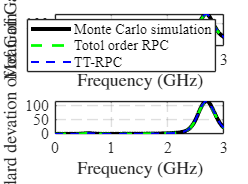

close all

y_mean0 = mean(abs(y_test));
y_sigma0 = std((y_test));

y_mean1 = mean(abs(y_predict));
y_sigma1 = std((y_predict));

y_mean2 = mean(abs(y_predict2));
y_sigma2 = std((y_predict2));

fpoints = linspace(10,3e6,100);
scale = 1e6;
f = figure(1);
subplot(2,1,1);
hold on
plot(fpoints/scale,y_mean0,'k-','LineWidth',3);
plot(fpoints/scale,y_mean1,'g--','LineWidth',2);
plot(fpoints/scale,y_mean2,'b--','LineWidth',1.5);
legend('Monte Carlo simulation','Totol order RPC', 'TT-RPC')
grid on
xlabel('Frequency (GHz)','interpreter','LaTex')
ylabel('Mean of Gain','interpreter','LaTex')
set(gca,'GridLineStyle','--')
set(gca, 'FontName', 'Times New Roman')
set(gca,'FontSize',12)
box on;

subplot(2,1,2);
hold on
plot(fpoints/scale,y_sigma0,'k-','LineWidth',3);
plot(fpoints/scale,y_sigma1,'g--','LineWidth',2);
plot(fpoints/scale,y_sigma2,'b--','LineWidth',1.5);

grid on
ylabel('Standard devation of of Gain','interpreter','LaTex')
xlabel('Frequency (GHz)','interpreter','LaTex')
set(gca,'GridLineStyle','--')
set(gca, 'FontName', 'Times New Roman')
set(gca,'FontSize',12)
box on;

f.Position = [100 100 675 500];

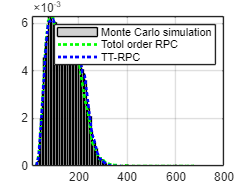



f_k = 90;

f = figure(2);
Hmc = histogram(abs(y_test(:,f_k)) ,50,'Normalization','pdf', 'DisplayStyle','bar', 'FaceColor',[0.7 0.7 0.7]);
hold on
grid on
[N_k,edges] = histcounts(abs(y_predict(:,f_k)), 'Normalization', 'pdf');
plot(edges(1:end-1)+(edges(2)-edges(1))/2,N_k,'g:','LineWidth',2)
[N_k,edges] = histcounts(abs(y_predict2(:,f_k)), 'Normalization', 'pdf');
plot(edges(1:end-1)+(edges(2)-edges(1))/2,N_k,'b:','LineWidth',2)
legend('Monte Carlo simulation','Totol order RPC', 'TT-RPC')